# Лабораторная работа №6

Решение АПСЗ скалярных произведений.

Генерация матриц:

n = 10;
eps = 1e-12;
disp('Собственные числа:')

Собственные числа:


d = randi(100, n, 1)

d =     75
    84
    27
    52
    45
    35
    84
    99
    63
    19


A = gen_matr2(d);
max_it = 1e4;


Поиск минимального СЧ:

Y_min = eye(n, 1);
[lambda_min, X_min, k_min, flag_min] = sp_min(A, Y_min, eps, max_it);
if flag_min == 0 %решение не достигнуто
    disp('Решение не достигнуто. Возможно не хватило максимального количества итераций или неверно задана погрешность');
end
if flag_min == 1 %решение достигнуто
    disp('Минимальное собственное число: ');
    lambda_min
    disp('Соответствующий нормированный собственный вектор: ');
    X_min
    disp('Число итераций: ');
    k_min
end

Минимальное собственное число: 


lambda_min = 19.0000

Соответствующий нормированный собственный вектор: 


X_min =     0.1810
    0.1898
    0.0033
   -0.1735
   -0.2194
   -0.1022
    0.1303
    0.2069
    0.0741
    0.8816


Число итераций: 


k_min = 61

Построение зависимости кол-ва итераций от погрешности для хорошо отделяемых СЧ:

[N, XX, LL, AL, E] = get_ne(-1, -16, 10, 1);

CЧ


d =     93
    53
    63
    69
    93
    16
    41
    32
    70
    90


> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_functi

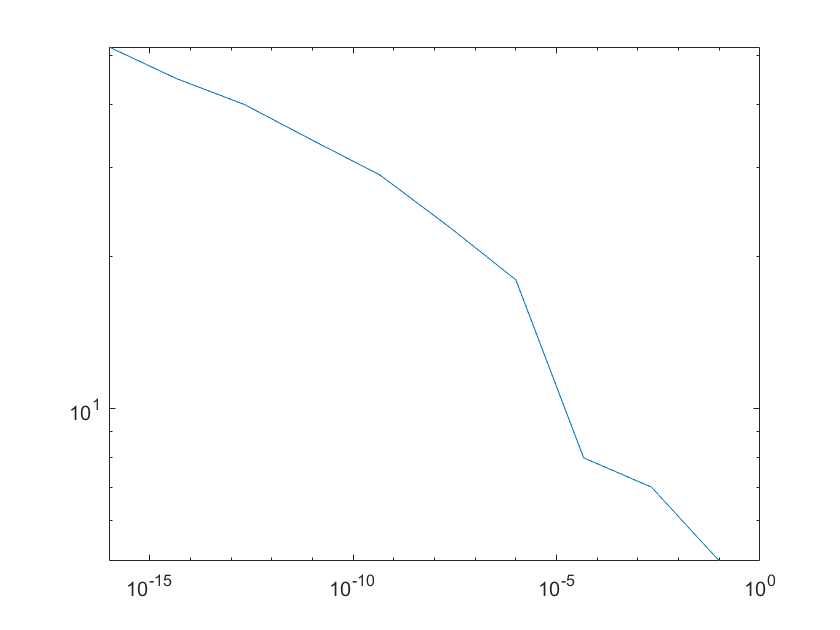

loglog(E, N);

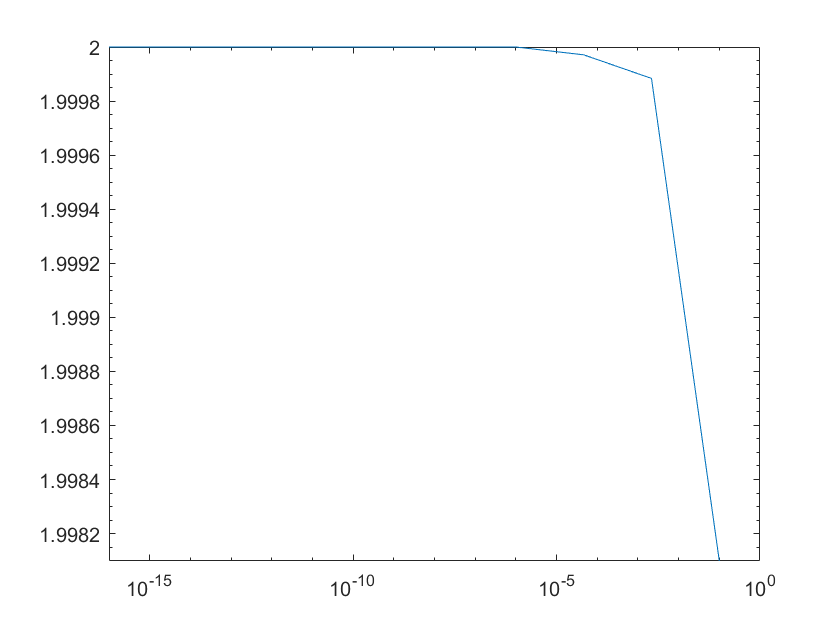

loglog(E, XX);

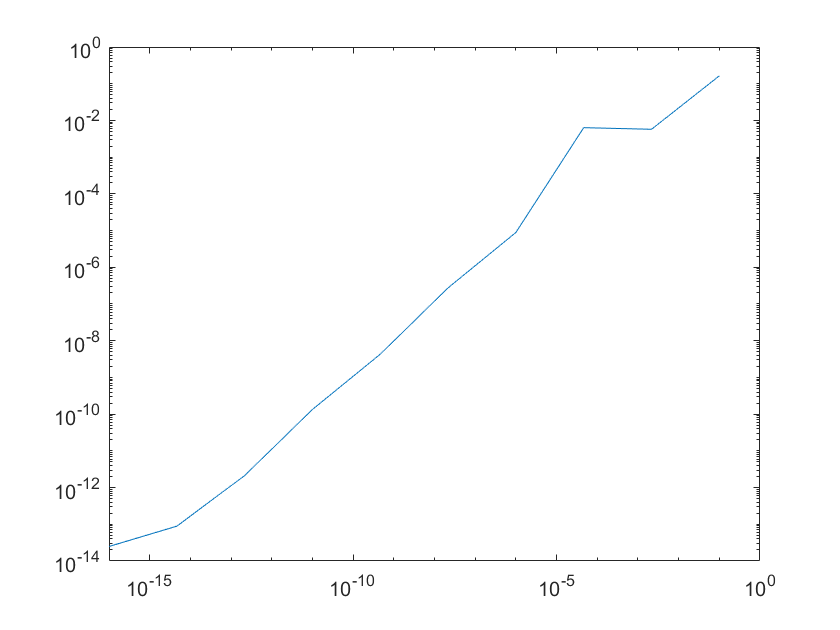

loglog(E, LL);

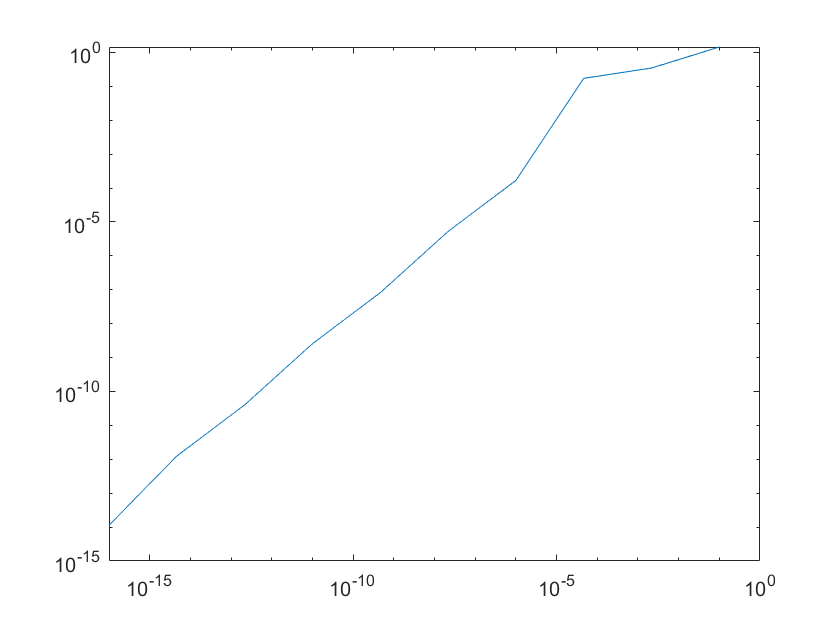

loglog(E, AL);

Построение зависимости кол-ва итераций от погрешности для плохо отделяемых СЧ:

[N, XX, LL, AL, E] = get_ne(1, -36, 100, 0);

CЧ


d =    10.0056
   10.0817
   10.0529
   10.0694
   10.0212
   10.0543
   10.0703
   10.0956
   10.0445
   10.0085


> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In sp_min (line 11)
  In parallel_functi

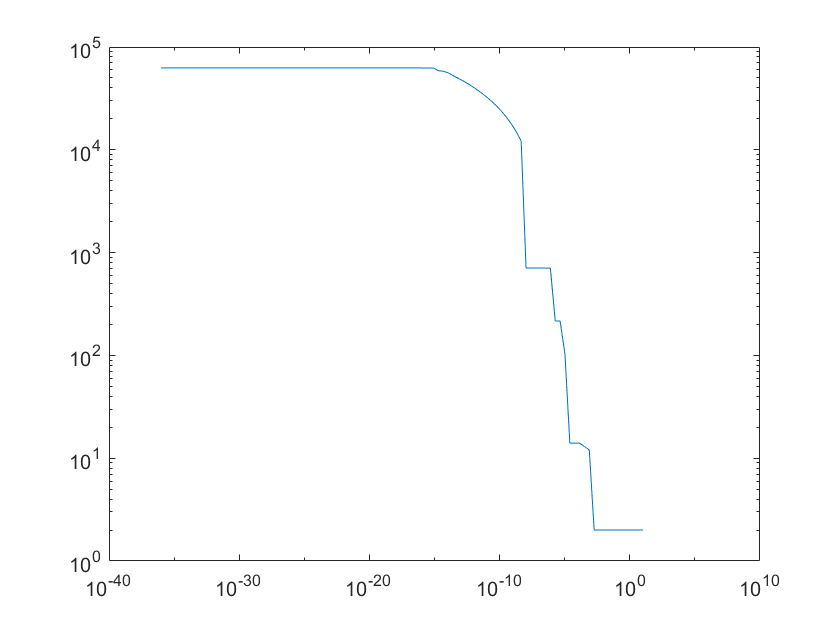

loglog(E, N);

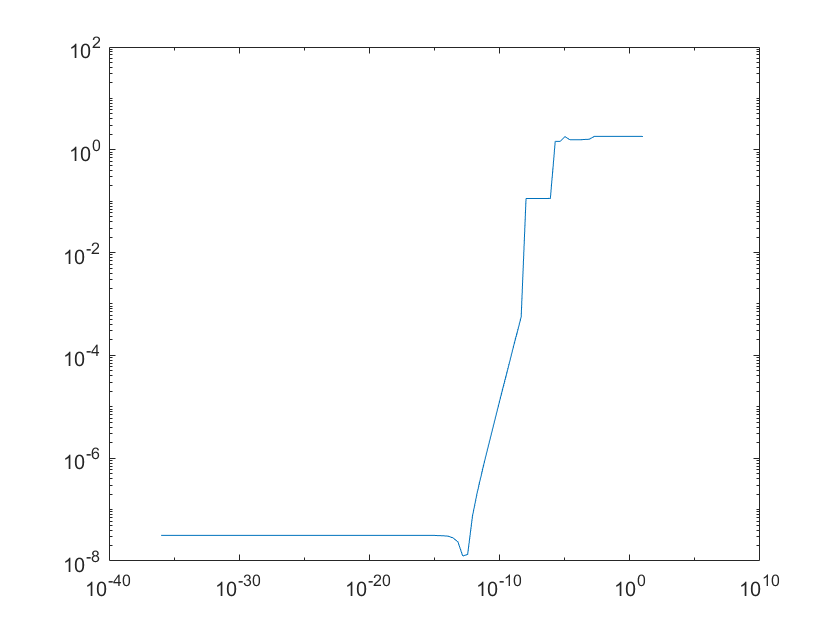

loglog(E, XX);

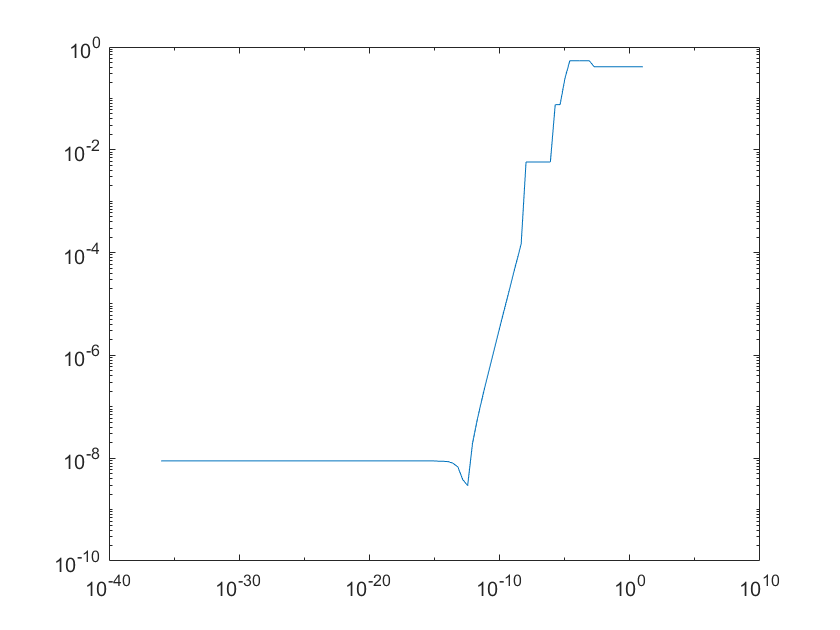

loglog(E, LL);

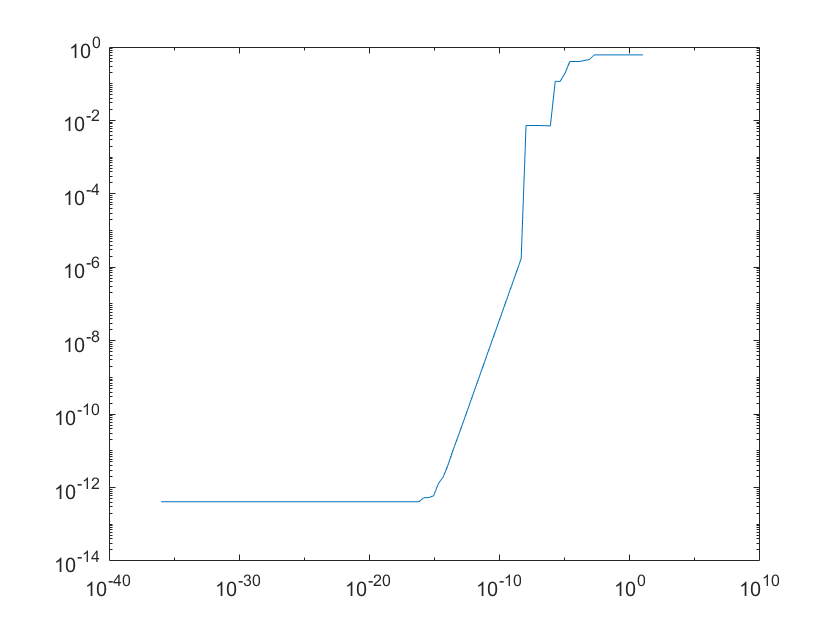

loglog(E, AL);

function A = gen_matr2(d)
    n = max(size(d));
    for i = 1:n
        for j = i+1:n
            A(i, j) = rand;
        end
        A(i, i) = d(i);
    end
    w = sin([1:1:n])';
    P = eye(n) - (2 * w * w')/(w' * w); 
    A = P*A*P'; 
end 

function [N, XX, LL, AL, eps_v] = get_ne(emin, emax, step, flag)
    eps_v = logspace(emin, emax, step);
    N = zeros(1, max(size(eps_v)));
    XX = zeros(1, max(size(eps_v)));
    LL = zeros(1, max(size(eps_v)));
    AL = zeros(1, max(size(eps_v)));
    if flag
        disp('CЧ')
        d = randi(100, 10, 1)
    else
        disp('CЧ')
        d = 10.*ones(10, 1) + rand(10, 1)./10
    end
    A = gen_matr2(d);
    [V, D] = eig(A);
    D = diag(D);
    [MIN, I] = min(D);
    Xmin = V(:, I);
    Y_min = eye(10, 1);
    parfor i = 1:max(size(eps_v))
        [lm, Xm, NN, flag] = sp_min(A, Y_min, eps_v(i), 1e20);
        N(i) = NN;
        XX(i) = norm(Xmin - Xm);
        LL(i) = abs(MIN - lm);
        AL(i) = norm(A*Xm - lm*Xm);
    end
end